# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 5.6.3 Phase Gradient

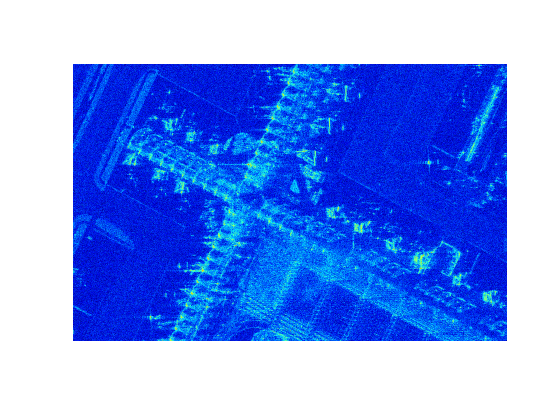

[file,path] = uigetfile('*.h5');
filename = fullfile(path,file);

% Form complex image data
s_i = h5read(filename, '/s_i');
s_q = h5read(filename, '/s_q');
s = double(s_i) + 1j * double(s_q);

clear s_i s_q

% Dynamic range for the image
dynamic_range = 60;

% Data size
[nx, ny] = size(s);
ratio = ny/nx;

% Offset from image center
offset_x = 0;
offset_y = 0;

xc = round(nx/2) - offset_x;
yc = round(ny/2) - offset_y;

% Specify a span / or fixed aspect
xs = 500;
ys = 1500;
% ys = round(ratio * xs);

% For full image
% xs = nx/2-1;
% ys = ny/2-1;

index_x = xc-xs:xc+xs;
index_y = yc-ys:yc+ys;

% For specifying
% index_x = 1:19310;
% index_y = 1:5000;

xs = round( (index_x(end) - index_x(1)) / 2);
ys = round( (index_y(end) - index_y(1)) / 2);

% Extract desired image area
s = s(index_x, index_y);  [nx, ny] = size(s);

% Apply 4th order phase error
t = linspace(-3, 3, nx);
phi = 0.5 * (t.^4 + t.^2);

% Calculate the phase error term
phase_term = exp(1j * phi') * ones(1, ny);
sf = fftshift(fft(s), 1);
s_e = ifft(phase_term .* sf);

% Set dB threshold for circular shift
threshold_db = 38;
[s_c, phi_es] = pga(s_e', threshold_db);

% Iteratively perform phase gradient
for i = 1:5
    threshold_db = threshold_db - 0.5;
    [s_c, phi_e] = pga(s_c, threshold_db);
    phi_es = phi_es + phi_e;
end

% Original image
figure;
pcolor(flipud(db(s)')); shading flat; 
set(gca,'XTick',[], 'YTick', [])
colormap jet
caxis([-abs(dynamic_range), 0]);
axis square
pbaspect([ratio * xs / ys 1 1])

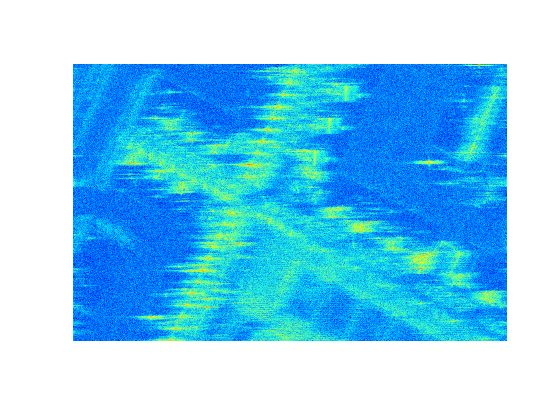


% Corrupted image
figure;
pcolor(flipud(db(s_e)')); shading flat; 
set(gca,'XTick',[], 'YTick', [])
colormap jet
caxis([-abs(dynamic_range), 0]);
axis square
pbaspect([ratio * xs / ys 1 1])

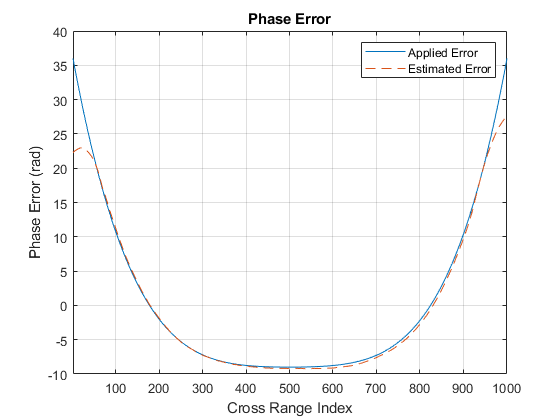


% Compare phase error
figure;
plot(phi); 
hold on; 
plot(-phi_es, '--');
title('Phase Error')
ylabel('Phase Error (rad)')
xlabel('Cross Range Index')
legend('Applied Error', 'Estimated Error');
xlim([1, length(phi)])
grid on

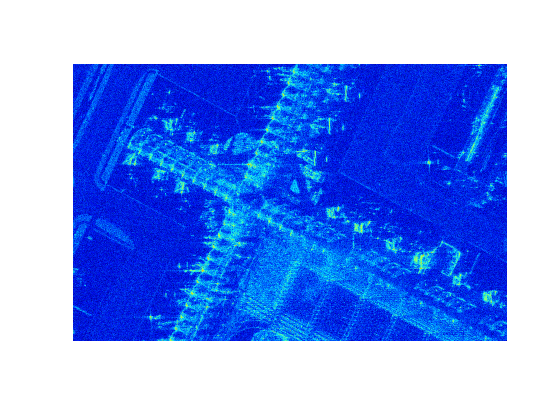


% Corrected image
figure;
pcolor(flipud(db(s_c))); shading flat; 
set(gca,'XTick',[], 'YTick', [])
colormap jet
caxis([-abs(dynamic_range), 0]);
pbaspect([ratio * xs / ys 1 1])